s = tf('s');
vin = 18;
L = 4E-3;
C = 10E-6;
r = 0.2;
R = 100;
kp = 0.1; 
R_i = 10E3;
fsw=30E3;
vo_d = vin/(L * C) * (1+ s * r * C) / (s^2 + s * ( 1/(R * C) + r/L)+ 1/(L * C))


vo_d =
 
     900 s + 4.5e08
  ---------------------
  s^2 + 1050 s + 2.5e07
 
Continuous-time transfer function.
Model Properties


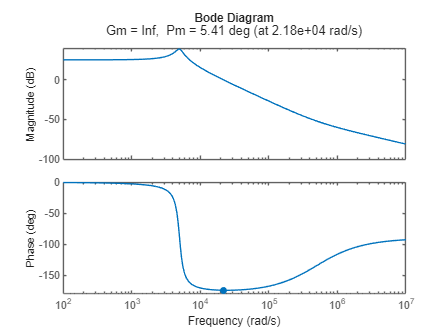


margin(vo_d)

r_f= kp * R_i; 
fc =1.3259e+03;
fz = fc/10;

wz = 2*pi*fz;  
C_cntrl=1/(r_f*wz)

C_cntrl = 7.9577e-08

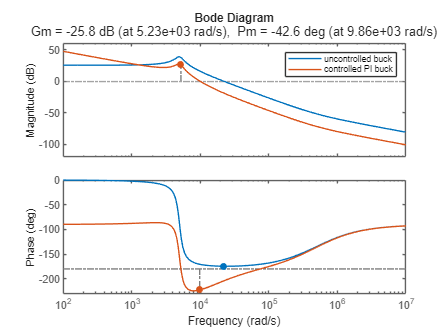

controller_num=r_f * C_cntrl; 
controller_den= R_i*C_cntrl;
            controller = tf([controller_num ,1] ,[controller_den, 0]);
closed= controller*vo_d; 
figure;

hold on; 
margin(vo_d);
margin(closed);
legend('uncontrolled buck', 'controlled PI buck');

[Gm,Pm,Wcg,Wcp] = margin(closed)

Gm = 0.0510

Pm = -42.5961

Wcg = 5.2305e+03

Wcp = 9.8582e+03

fz = fc/10

fz = 2000

fc_actual = Wcp / (2*pi)

fc_actual = 1.5690e+03